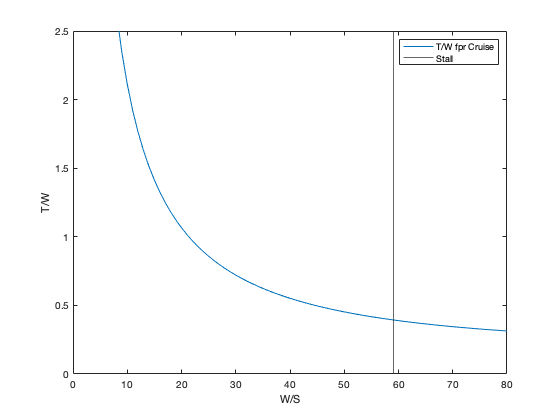

x = 1:80;
y = (21.065./x)+6.293e-4*x;
plot(x,y)
ylim([0,2.5])
xlabel('W/S')
ylabel('T/W')
hold on
xline(58.996)
legend('T/W fpr Cruise','Stall')
hold off

x = [106,2500,6400,680,22.5,950,5878,1044,2000,1060];
y = [223,6500,20200,934,30,2200,11600,1459,2840,1680];
tb1 = [106,223;2500,6500;6400,20200;680,934;22.5,30;950,2200;5878,11600;1044,1459;2000,2840;1060,1680]

tb1 = 	1.0e+04 *

   0.010600000000000   0.022300000000000
   0.250000000000000   0.650000000000000
   0.640000000000000   2.020000000000000
   0.068000000000000   0.093400000000000
   0.002250000000000   0.003000000000000
   0.095000000000000   0.220000000000000
   0.587800000000000   1.160000000000000
   0.104400000000000   0.145900000000000
   0.200000000000000   0.284000000000000
   0.106000000000000   0.168000000000000


CC=polyfit(log(y),log(x./y),1)

CC =   -0.094930828584146   0.091141577908457


A = CC(1)

A =   -0.094930828584146


B = CC(2)

B =    0.091141577908457


%Iterative take off weight
A1 = 500;
A2 = 0.8533;
A3 = -1.0954;
Wo = 10500;
e = 3;
dW = 6;
while dW > e
    Wo2 = A1/(A2+A3*(Wo^-0.0949));
    dW = abs(Wo2-Wo);
    Wo = Wo2
end

Wo =      1.255171675284498e+03


Wo =      1.684931771762773e+03


Wo =      1.602129223051836e+03


Wo =      1.615559452750198e+03


Wo =      1.613314614350530e+03


Wo2

Wo2 =      1.613314614350530e+03


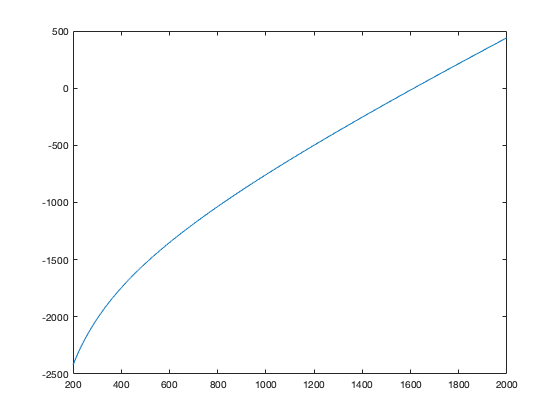

%Graphical take off weight
Wo = 200:2000;
A1 = 500;
A2 = 0.8533;
A3 = -1.0954;
y = Wo - (A1./(A2+A3*(Wo.^-0.0949)));
plot(Wo,y)

%performance sensitivity analysis(PL)
dWpl = 0.5;
Wo = 1613.3

Wo =      1.613300000000000e+03


A1 = 500-dWpl/2;
A11 = 500+dWpl/2;
A2 = 0.8533;
A3 = -1.0954;
Wo = A1/(A2+A3*(Wo^-0.0949));
Wo2 = A11/(A2+A3*(Wo^-0.0949));
dWpl = (Wo2-Wo)/dWpl

dWpl =    3.366138473332285


%performance sensitivity analysis(R)
dR = .5;
Woi = 1613.3;
A1 = 500-dR/2;
A11 = 500+dR/2;
Rc = 1640820;
Rc2 = 1639180;
Cc = 5.556e-4;
LD = 6.312;
Vc = 775.78;
Wac = exp((-Rc2*Cc)/(Vc*LD));
Wst = 1;
Wxo = Wst*Wac;
Wfo = 1.06*(1-Wxo);
A2 = 1-Wfo;
A3 = -exp(0.0911);
Wac2 = exp((-Rc*Cc)/(Vc*LD));
Wxo2 = Wst*Wac2;
Wfo2 = 1.06*(1-Wxo2);
A22 = 1-Wfo2;
Wo = A1/(A2+A3*(Woi^-0.0949));
Wo2 = A11/(A22+A3*(Woi^-0.0949));
dRo = (Wo2-Wo)/1640.42

dRo =    0.001754521529182


%performance sensitivity analysis(Cd)
format long
%initial constants
dCo = 2.2e-3; %change in drag coeff
Woi = 1613.3; %initial weight
WSc = 51.327; %wing loading cruise
AR = 8.5; % aspect ratio
e = 0.6; %oswald coeff
q = 268.094; 
Rc = 1640000; %Cruise range
Cc = 5.556e-4;% Cruise spec fuel consump
Vc = 775.7464; %Cruise velocity
A3 = -exp(0.0911);
%Two sides of differential
A1 = 0.022-dCo/2;
A11 = 0.022+dCo/2;

Lac = 1/(((q*A1)/WSc)+(WSc/(q*AR*pi*e)));
Wac = exp((-Rc*Cc)/(Vc*Lac));
Wst = 1;
Wxo = Wst*Wac;
Wfo = 1.06*(1-Wxo)

Wfo =    0.140561229768838


A2 = 1-Wfo

A2 =    0.859438770231162



Lac2 = 1/(((q*A11)/WSc)+(WSc/(q*AR*pi*e)))

Lac2 =    7.541115079490473


Wac2 = exp((-Rc*Cc)/(Vc*Lac2))

Wac2 =    0.855766142289280


Wxo2 = Wst*Wac2;
Wfo2 = 1.06*(1-Wxo2);
A22 = 1-Wfo2;

Wo = 500/(A2+A3*(Woi^-0.0949))

Wo =      1.582287517952227e+03


Wo2 = 500/(A22+A3*(Woi^-0.0949));

dCd = (Wo2-Wo)/dCo

dCd =      2.919470099214054e+04
